% ----------------------------------------------------------------------
%   Spherical Linear Intepolation (slerp) and 
%   Screw Linear Interpolation (sclerp)
%    20210108  y.yoshimura
%    Inputs:
%   Outputs:
%   related function files:
%   note:
%   cf:
%   revisions;
%   
%   (c) 2021 yasuhiro yoshimura
%----------------------------------------------------------------------

clc
clear
close all


## load object

sat = readSC('oneWeb.obj');

number of vertices:
   654

number of faces:
        1296




showSC(sat)


## quaternions to be interpolated

q1 = [0 0 0 1];
q1 = rand(1,4);
q1 = q1 ./ norm(q1);

q2 = rand(1,4);
q2 = q2 ./ norm(q2);


## slerp

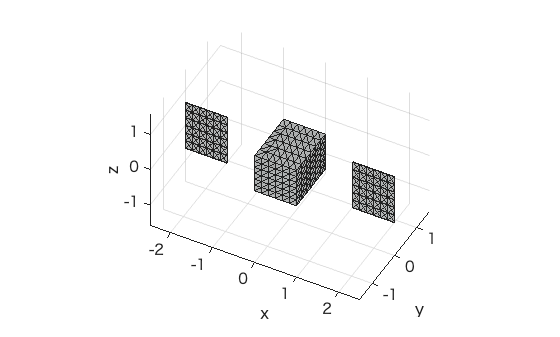

dt = 0.01;
t = 0:dt:1;

% interpolated quaternion, q1 → q2
qt = slerp(t, 4, q1, q2);

tiledlayout(4,1);

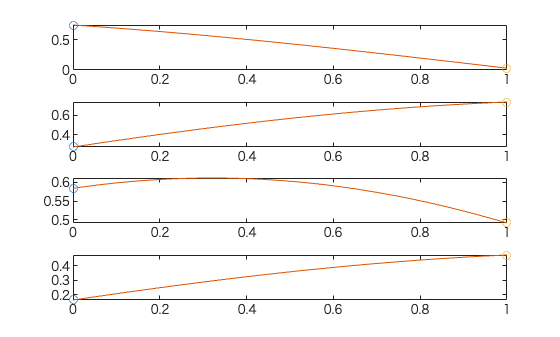

nexttile
plot(t(1), q1(1), 'o');
hold on
plot(t, qt(:,1));
plot(t(end), q2(1), 'o');
nexttile
plot(t(1), q1(2), 'o');
hold on
plot(t, qt(:,2));
plot(t(end), q2(2), 'o');
nexttile
plot(t(1), q1(3), 'o');
hold on
plot(t, qt(:,3));
plot(t(end), q2(3), 'o');
nexttile
plot(t(1), q1(4), 'o');
hold on
plot(t, qt(:,4));
plot(t(end), q2(4), 'o');

## sclerp

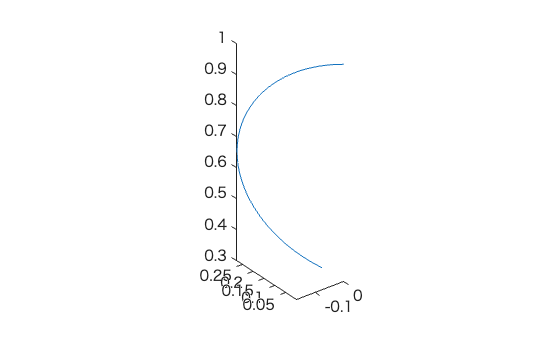

rI1 = [0 0.1 0.3]; % translation
dq1r = rand(1,4); % real part
dq1r = dq1r ./ norm(dq1r);
dq1r = [0 0 0 1];

dq1d = 0.5 .* qMult(4, 1, dq1r, [rI1 0]); % dual part
dq1 = [dq1r, dq1d];

rI2 = [0 0 1]; % translation
dq2r = rand(1,4); % real part
dq2r = dq2r ./ norm(dq2r);

dq2d = 0.5 .* qMult(4, 1, dq2r, [rI2 0]);
dq2 = [dq2r, dq2d];

% interpolated dual quaternion, dq1 → dq2
dqt = sclerp(t, 4, dq1, dq2);

[rI, q] = dq2pos(1, 4, dqt);


figure
plot3(rI(:,1), rI(:,2), rI(:,3))
axis equal

## show DQ figs

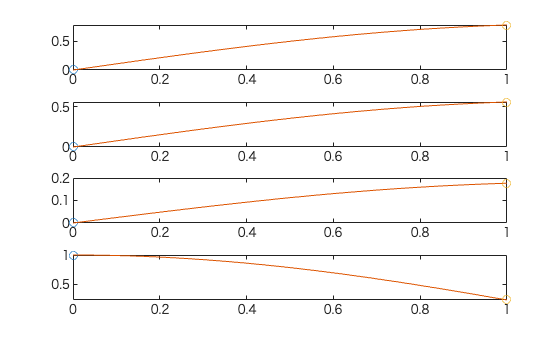

figure % real part
tiledlayout(4,1);
nexttile
plot(t(1), dq1(1), 'o');
hold on
plot(t, dqt(:,1));
plot(t(end), dq2(1), 'o');
nexttile
plot(t(1), dq1(2), 'o');
hold on
plot(t, dqt(:,2));
plot(t(end), dq2(2), 'o');
nexttile
plot(t(1), dq1(3), 'o');
hold on
plot(t, dqt(:,3));
plot(t(end), dq2(3), 'o');
nexttile
plot(t(1), dq1(4), 'o');
hold on
plot(t, dqt(:,4));
plot(t(end), dq2(4), 'o');

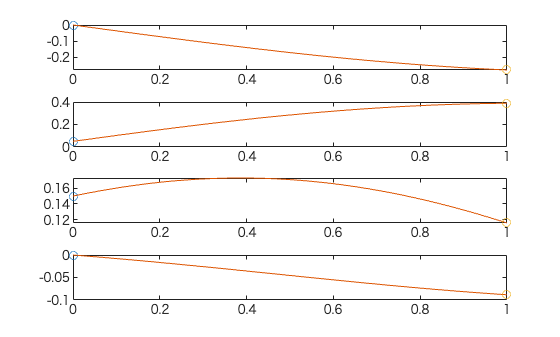


figure % dual part
tiledlayout(4,1);
nexttile
plot(t(1), dq1(5), 'o');
hold on
plot(t, dqt(:,5));
plot(t(end), dq2(5), 'o');
nexttile
plot(t(1), dq1(6), 'o');
hold on
plot(t, dqt(:,6));
plot(t(end), dq2(6), 'o');
nexttile
plot(t(1), dq1(7), 'o');
hold on
plot(t, dqt(:,7));
plot(t(end), dq2(7), 'o');
nexttile
plot(t(1), dq1(8), 'o');
hold on
plot(t, dqt(:,8));
plot(t(end), dq2(8), 'o');


%% satellite pose
% figure
% % hold on
% axis equal
% grid on
% xlabel('x'), ylabel('y'), zlabel('z')
% xlim([-3 3]), ylim([-3 3]), zlim([-3 3])
% h = patch('Faces',sat.faces,'Vertices', sat.vertices, 'facecolor', [0.0 0 0.2]);
% alpha(0.4);
% hold on
% % target pose
% dq_tmp = kron(ones(length(sat.vertices),1), dq2);
% ri = 2 * qMult(4, 0, dq2(1,5:8), qInv(4,dq2(1,1:4)))
% newVertices = dqRotation(4, sat.vertices, dqInv(4,dq_tmp));
% newVertices = newVertices + kron(ones(size(sat.vertices,1),1), ri(:,1:3));
% patch('Faces',sat.faces,'Vertices', newVertices, 'facecolor', [0 0.5 0]);
% 
% view([64 15])
% 
% for i = 1:length(dqt)
% dq_tmp = kron(ones(length(sat.vertices),1), dqt(i,:));
% ri = 2 * qMult(4, 0, dqt(i,5:8), qInv(4,dqt(i,1:4)));
% newVertices = dqRotation(4, sat.vertices, dqInv(4,dq_tmp));
% newVertices = newVertices + kron(ones(size(sat.vertices,1),1), ri(:,1:3));
% set(h, 'Vertices', newVertices, 'facecolor', [0 0 0.2]);
% drawnow
% pause(0.05)
% end
% ↑ vector rotationなので qInvを使っている．

% figure
% hold on
% patch('Faces',sat.faces,'Vertices', newVertices, 'facecolor', [0 0 1]);
% axis equal
% grid on
% xlabel('x'), ylabel('y'), zlabel('z')
